# On-Off Control Analysis

Simulation analysis of On-Off controller implementation.

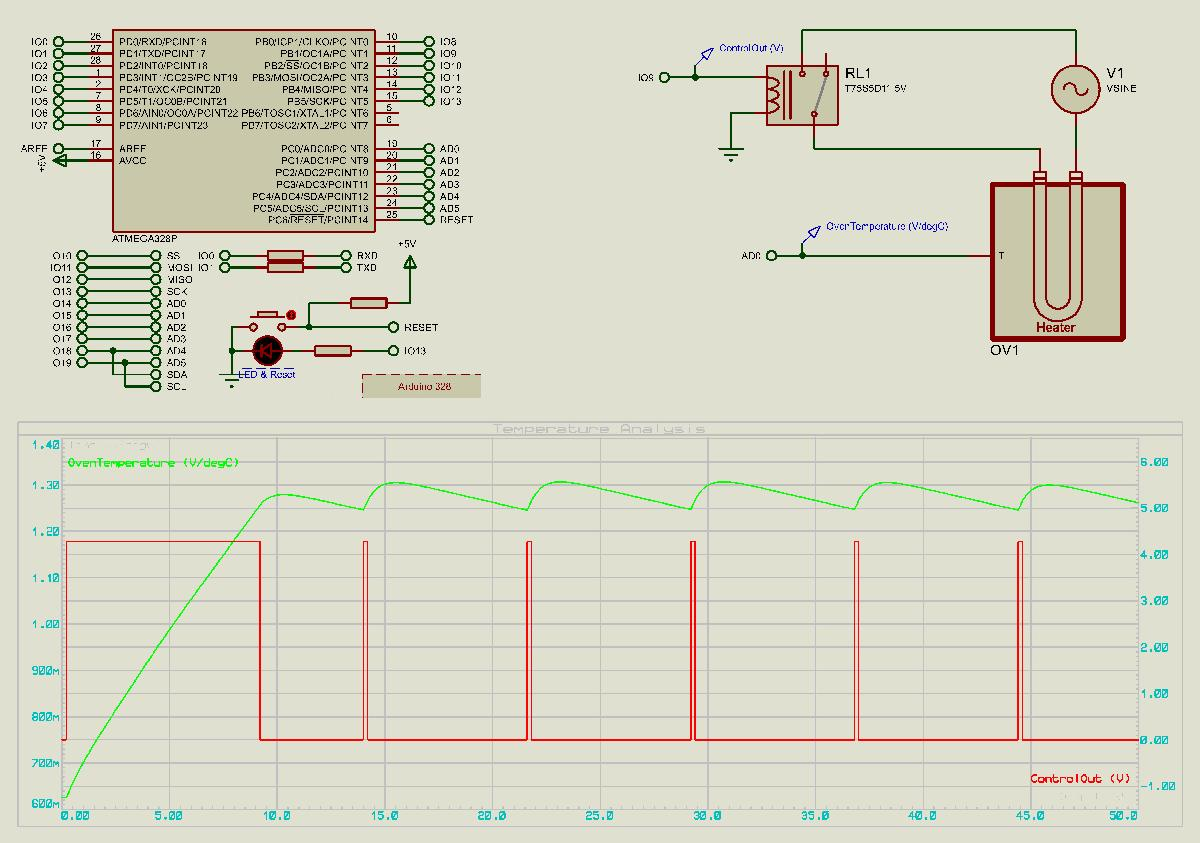

#### Analyzing Simulation Data

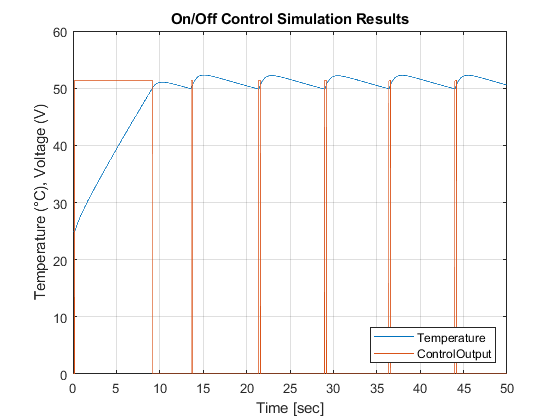

clear,clc;
% read simulation data into a table
simData = readtable('OnOffControl_SIM1Data.DAT');
% change column names for something easy to use
simData.Properties.VariableNames = {'Time','Tov','Control'};
V_step = 0.025;
% plot results
% multiply the temperature data by (1/V_step) to convert to °C
plot(simData.Time,simData.Tov*(1/V_step)); 
hold on
% the control output is scaled by 12 to make the figure easier to read
plot(simData.Time,simData.Control*12);
grid on; xlabel('Time [sec]'); ylabel('Temperature (°C), Voltage (V)');
title('On/Off Control Simulation Results')
legend('Temperature','ControlOutput','Location',"southeast");
hold off;

### Conclusion

From the simulation data, it is shown that the system is behaving as expected. However, we have a pulsating output in the temperature which we will be able to eliminate using a PI controller.